# Tipos de Software

## Software Simbólico

definimos la variable Temperatura que depende del tiempo

syms T(t)

A continuación definimos la EDO

k=0.023;
ta=30;
edo= diff(T)==k*(ta-T(t))

$$edo(t) = \frac{\partial }{\partial t}T\left(t\right)=\frac{69}{100}-\frac{23\,T\left(t\right)}{1000}$$

Finalmente introducimos las condiciones iniciales:

condini= T(0)==600;

Y resolvemos la EDO

solsimb=dsolve(edo,condini)

$$solsimb = 570\,{\mathrm{e}}^{-\frac{23\,t}{1000}}+30$$

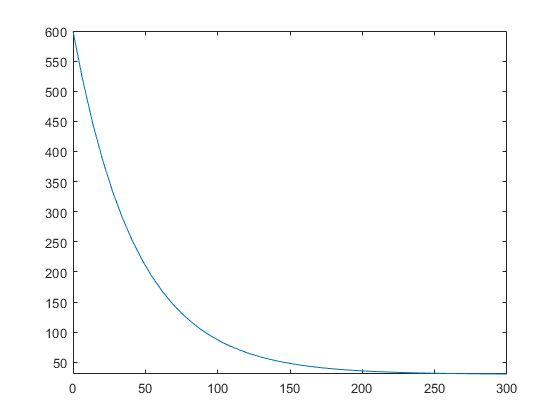

fplot(solsimb,[0 300])

solsimbnoci=dsolve(edo)

$$solsimbnoci = C_{1}\,{\mathrm{e}}^{-\frac{23\,t}{1000}}+30$$

## Software numérico

definimos la función a resolver

resolvemos el sistema

[t,T]=ode45(@enfriamiento2, [0 300], 600);


Dibujamos

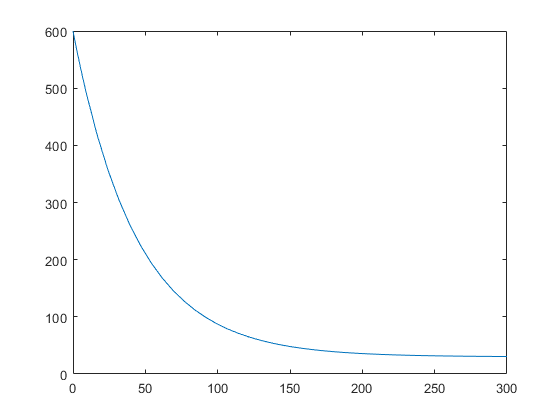

plot(t,T)

Comparamos la solución de ambos problemas

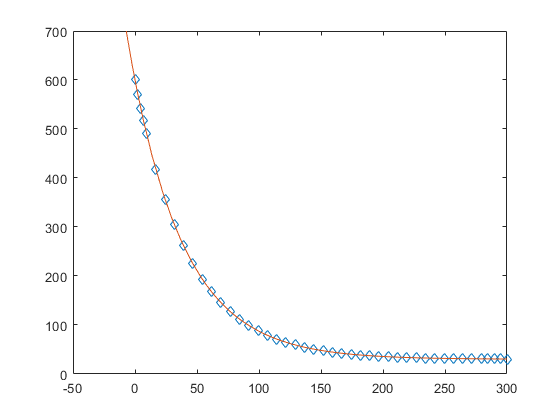

plot(t,T,'d')
hold on
fplot(solsimb)
hold off